# How to programmatically configure a Simulink simulation?

[ ](https://matlab.mathworks.com/open/github/v1?repo=simulink/blog&project=2025_06_20_WhatsThis/WhatsThis.prj)

Here is another frequently viewed [MATLAB Answers](https://www.mathworks.com/matlabcentral/answers/help) post:

[Set simulation time and fixed step size for a Simulink model from the command line](https://www.mathworks.com/matlabcentral/answers/254468-set-simulation-time-and-fixed-step-size-for-a-simulink-model-from-the-command-line)

While this question asks specifically about [stop time](https://www.mathworks.com/help/simulink/gui/stoptime.html) and solver [step size](https://www.mathworks.com/help/simulink/gui/fixedstepsizefundamentalsampletime.html), I think this can be generalized to this question: *How to find the programmatic equivalent of a block or model setting in Simulink?*

My answer is: Use **What's This?**

## Model Parameters

In case you never noticed, you can right-click on most configset parameters to see a "What's This?" menu being offered:

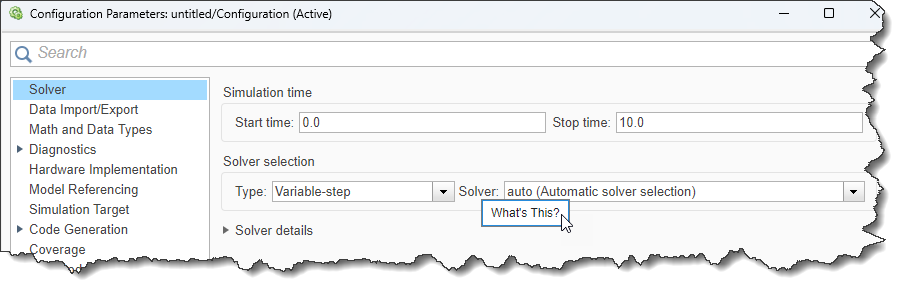

Clicking it opens a short description of the setting and the programmatic equivalent:

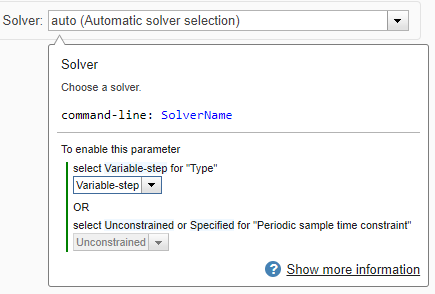

Clicking the **Show more information** link opens a separate **What's This Help** window with more details:

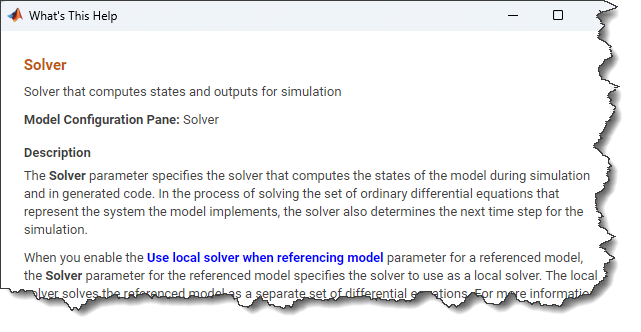

If you scroll toward the bottom, you will find a table listing everything you need to know about the programmatic use for this setting:

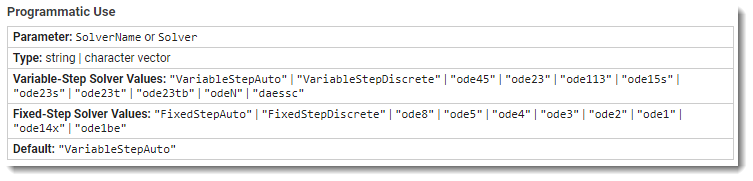

## Block Parameters

Most blocks parameters also have a What's This?:

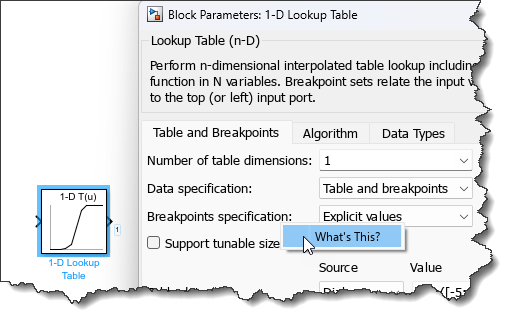

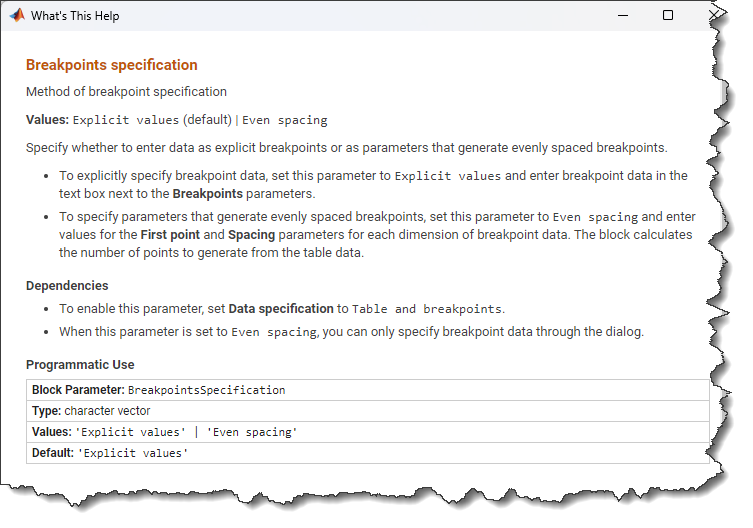

Now that we know how to obtain parameter names and possible values, let's see how to apply them.

## Modifying the model

If you want to modify the model with the new setting value, use [`set_param`](https://www.mathworks.com/help/simulink/slref/set_param.html). For the settings described above, this looks like:

mdl = 'MyTestModel';% The name of the SLX file
open_system(mdl);

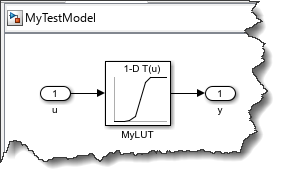

Let's check what's the original value using [`get_param`](https://www.mathworks.com/help/simulink/slref/get_param.html), change it, and confirm that it has changed:

get_param(mdl,'SolverName')

ans = 'VariableStepAuto'

set_param(mdl,'SolverName','ode45')
get_param(mdl,'SolverName')

ans = 'ode45'

The same works for blocks:

blk = 'MyTestModel/MyLUT'; %The path of the block
get_param(blk,'BreakpointsSpecification')

ans = 'Explicit values'

set_param(blk,'BreakpointsSpecification','Even spacing');
get_param(blk,'BreakpointsSpecification')

ans = 'Even spacing'

At this point, you can save your changes using [save_system](https://www.mathworks.com/help/simulink/slref/save_system.html)

## Simulating with different parameter values

In some cases, you want to simulate the model with different parameter values, but not dirty or modify the model file. For that, I recommend using a [Simulink.SimulationInput](http://simulink.simulationinputhttps//www.mathworks.com/help/simulink/slref/simulink.simulationinput.html) object. Here is an example where I simulate a model with 3 different solvers:

mdl = 'testStep';
open_system(mdl);

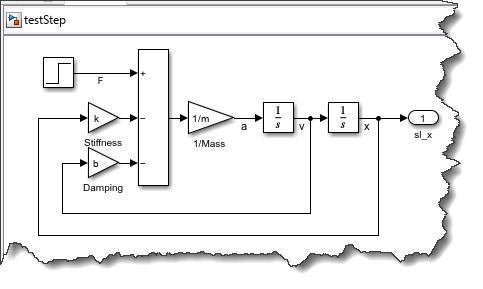

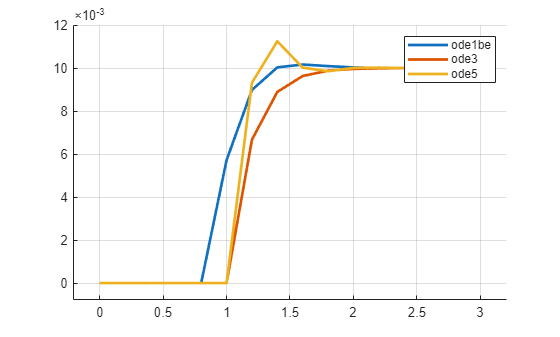

solverChoices = {'ode1be','ode3','ode5'};
N = length(solverChoices);
% Creating an array of Simulink.Simulationinput objects
in = repmat(Simulink.SimulationInput(mdl),N,1);
% specify different solvers for each simulation
in = arrayfun(@(i) in(i).setModelParameter('SolverName',solverChoices{i}),1:N);
out = sim(in,'ShowProgress','off');
% Plot results
figure; hold on;
arrayfun(@(i) plot(out(i).yout{1}.Values),1:N);
legend(solverChoices)

## Now it's your turn

How do you find the programmatic way to configure Simulink? Let us know in the comments below.